# Create a dataset to play with

While it is certainly possible to find pre-existing datasets, it is also possible to just create your own. This script walks you through collecting two datasets by selecting points on a graph. 

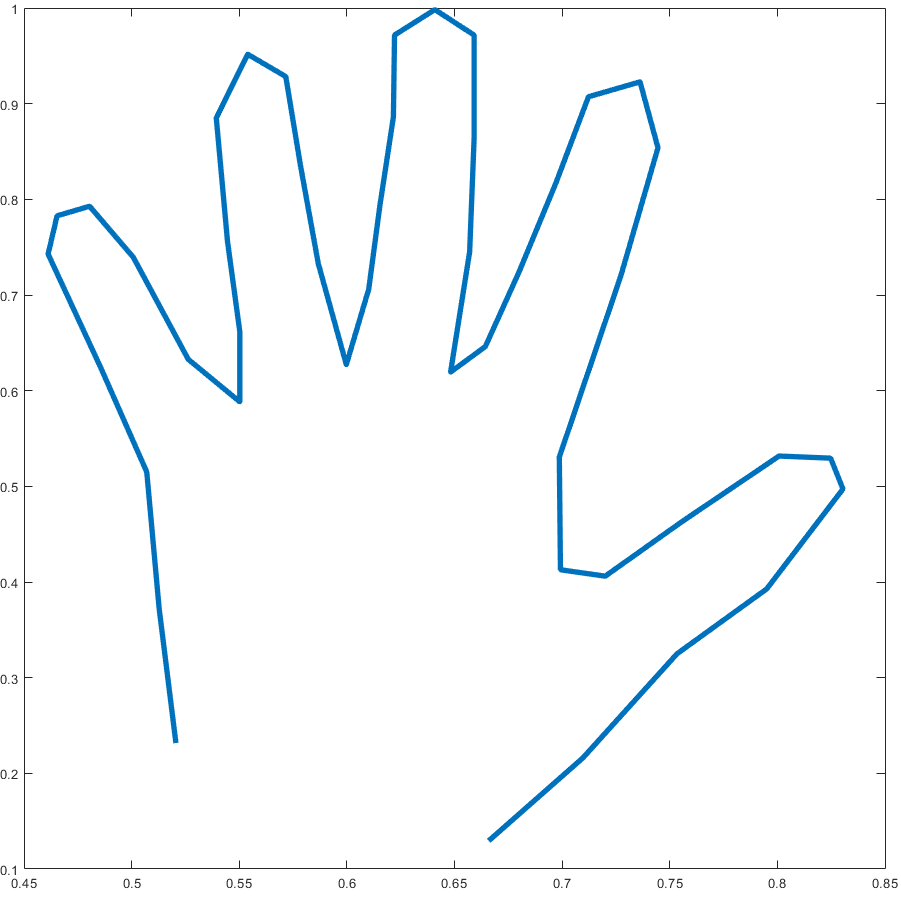            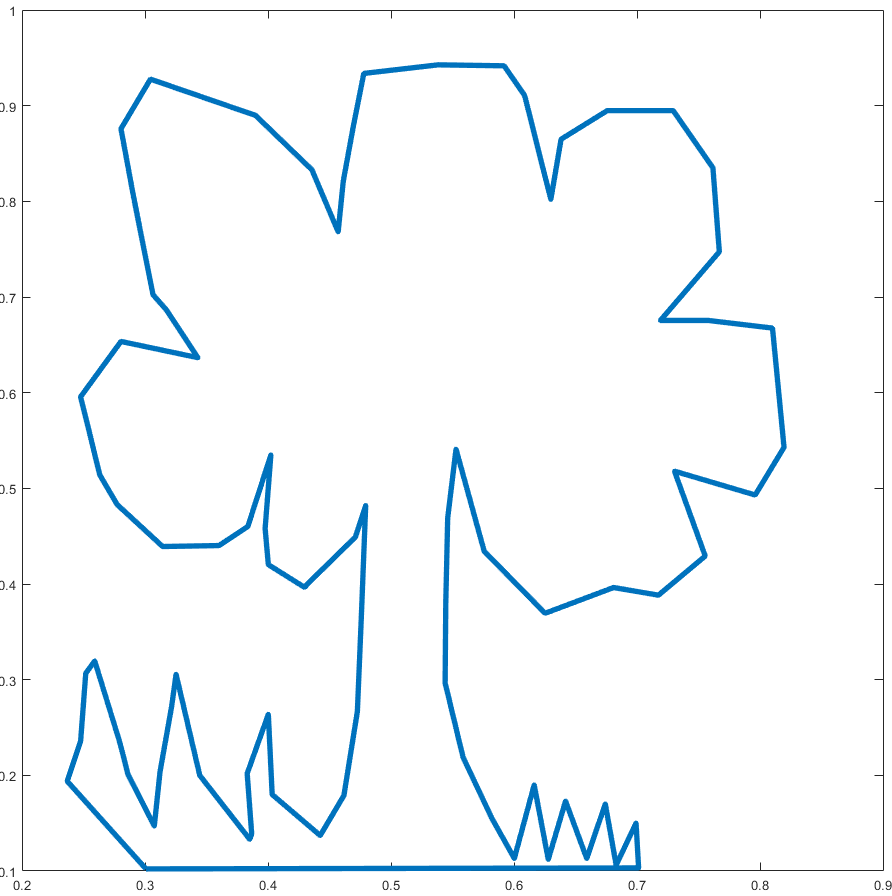

- Trace your hand

- Draw a closed-loop image

[x,y] = collectData();

#### Check your dataset

Are you satisfied with the result?

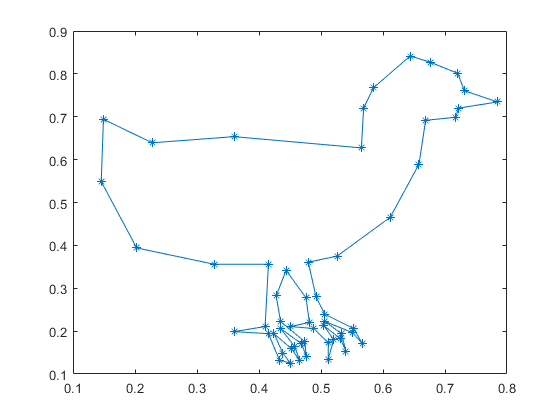

% To enforce a loop that is closed, you can connect the last data point to the first
% data point by uncommenting the code below by adding the first element to
% the end of the variables x and y
% x = [x; x(1)];
% y = [y; y(1)];
clf
% Plot a line connecting each of your points in order

plot(x,y,"*-")

#### Save your dataset

Choose the appropriate label for your dataset and then save. If you create a later dataset that you like more, selecting the same name in the dropdown in this section will overwrite your earlier file. Then go back and repeat this process to save another dataset as `drawing.mat` by setting the dropdown menu appropriately in this section.

% Save the data x and y with the name selected in the dropdown
% in the Data directory
save Data/hand.mat x y

#### Helper functions

function [x,y] = collectData()
% figure('position',get(0,'screensize'))
% figure("WindowState","maximized")
axes('position',[0 0 1 1])
grid on
grid minor
str = ["Select control points around your image by clicking and then double-click ", ...
    "to finish data collection. Close the figure window to return to the script."];
annotation("textbox",[.05 .9 .1 .1],"String",str,"FitBoxToText","on")
ax = gca;
roi = drawpolygon(ax);
x = roi.Position(:,1);
y = roi.Position(:,2);
end